# Lab IV - State Observers and Estimators

clc
clear 
addpath('C:\Users\laura\Documents\2026-2\Control Digital\Funciones')
addpath('C:\Users\laura\Documents\2026-2\Control Digital\Laboratories\Lab III\')

## Parametric Identification

LabIII Measurements

f_osc  = 1/(320e-6);    % encoder signal frequency [Hz]
CPR    = 16;            % counts per motor revolution (single edge)
N      = 50;            % gear ratio
Va_nom = 12;            % nominal voltage [V]
ia     = 0.230;         % no-load current at 12 V [A]
Ra     = 1.9;           % armature resistance, multimeter, motor off [Ohm]
I_ref  = 5.5;           % datasheet current used for Za [A]
eg     = 10.858;        % generator voltage (coupled motors) [V]
tm     = 0.0200559;     % mechanical time constant [s]

Parameter Calculations

w_m  = 2*pi*f_osc/CPR;              % motor speed [rad/s]
Za   = Va_nom/I_ref;                % [Ohm]
La   = sqrt(Za^2 - Ra^2)/w_m;       % armature inductance [H]
Kv   = eg/w_m;                      % back-EMF / torque constant [V*s/rad]
beta = Kv*ia/w_m;                   % viscous friction [N*m*s/rad]
J    = tm*Kv^2/Ra;                  % rotor inertia [kg*m^2]

Params = table(Ra, La, Kv, beta, J)

Params = 1×5 table
    Ra         La           Kv           beta           J     
    ___    __________    _________    __________    __________

    1.9    0.00087398    0.0088479    1.6583e-06    8.2636e-07


Model in Differential Equations (syms)

syms i_a(t) w(t) Va

eq_elec = vpa(La*diff(i_a,t) + Ra*i_a + Kv*w == Va, 4)   % electrical

$$eq\_elec(t) = 0.000874\,\frac{\partial }{\partial t}i_{a}\left(t\right)+1.9\,i_{a}\left(t\right)+0.008848\,w\left(t\right)=\mathrm{Va}$$

eq_mech = vpa(J*diff(w,t) + beta*w == Kv*i_a, 4)          % mechanical

$$eq\_mech(t) = 8.264e-7\,\frac{\partial }{\partial t}w\left(t\right)+1.658e-6\,w\left(t\right)=0.008848\,i_{a}\left(t\right)$$


% Single 2nd-order ODE in w (eliminating i_a)
a2 = J*La;  a1 = J*Ra + La*beta;  a0 = Ra*beta + Kv^2;
eq_w = vpa(a2*diff(w,t,2) + a1*diff(w,t) + a0*w == Kv*Va, 4)

$$eq\_w(t) = 7.222e-10\,\frac{\partial^{2}}{\partial t^{2}}w\left(t\right)+1.572e-6\,\frac{\partial }{\partial t}w\left(t\right)+8.144e-5\,w\left(t\right)=0.008848\,\mathrm{Va}$$

State-Space Representation

A = [-Ra/La, -Kv/La;
    Kv/J,  -beta/J];
B = [1/La; 0];
C = [0 1];
D = 0;

sys_ss = ss(A, B, C, D, 'StateName', {'i_a','\omega'}, ...
    'InputName', 'V_a', 'OutputName', '\omega')


sys_ss =
 
  A = 
                 i_a     \omega
   i_a         -2174     -10.12
   \omega  1.071e+04     -2.007
 
  B = 
            V_a
   i_a     1144
   \omega     0
 
  C = 
              i_a  \omega
   \omega       0       1
 
  D = 
           V_a
   \omega    0
 
Continuous-time state-space model.


Transfer Functions

s = tf('s');

G_w  = tf(Kv/a2, [1, a1/a2, a0/a2])   % Omega(s)/Va(s)  [rad/s / V]


G_w =
 
         1.225e07
  -----------------------
  s^2 + 2176 s + 1.128e05
 
Continuous-time transfer function.


G_th = G_w/s                          % Theta(s)/Va(s)  [rad / V]


G_th =
 
           1.225e07
  ---------------------------
  s^3 + 2176 s^2 + 1.128e05 s
 
Continuous-time transfer function.


Step Response (to nominal, 12v)

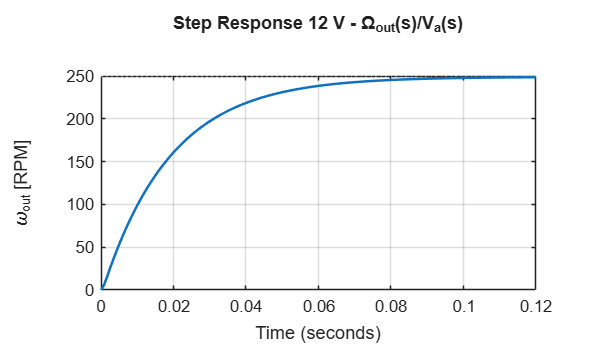

G_out_rpm = G_w * 60/(2*pi*N);

figure;
step(Va_nom*G_out_rpm, 'LineWidth', 1.5); grid on;
title('Step Response 12 V - \Omega_{out}(s)/V_a(s)');
xlabel('Time'); ylabel('\omega_{out} [RPM]');

## Non-Parametric Identification

Importing Data Extracted from LabView

data = readtable('inp.xlsx');

head(data); 

     t1      u1     y1       t2      u2    y2     t3      u3    y3
    _____    __    _____    _____    __    __    _____    __    __

        0    10       15        0    0     0         0    0     0 
    0.005    10       15    0.005    0     0     0.005    0     0 
     0.01    10    18.75     0.01    0     0      0.01    0     0 
    0.015    10       15    0.015    0     0     0.015    0     0 
     0.02    10    18.75     0.02    0     0      0.02    0     0 
    0.025    10       15    0.025    0     0     0.025    0     0 
     0.03    10    18.75     0.03    0     0      0.03    0     0 
    0.035    10    18.75    0.035    0     0     0.035    0     0 



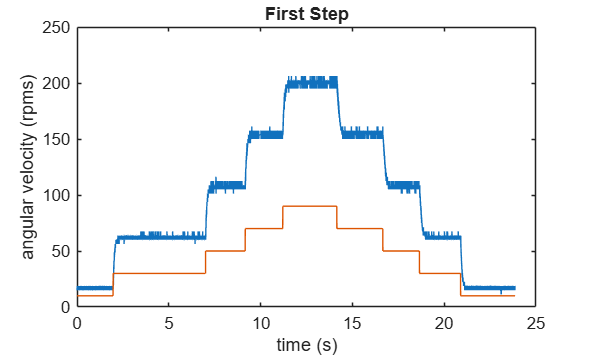

% First Measurement
t1 = data.t1;
u1 = data.u1;
y1 = data.y1; 


% Second Measurement
t2 = data.t2;
u2 = data.u2;
y2 = data.y2; 

% Third Measurement
t3 = data.t3;
u3 = data.u3;
y3 = data.y3; 

figure; 
plot(t1, y1);
hold on; 
plot(t1, u1);
title('First Step');
xlabel("time (s)")
ylabel("angular velocity (rpms)")

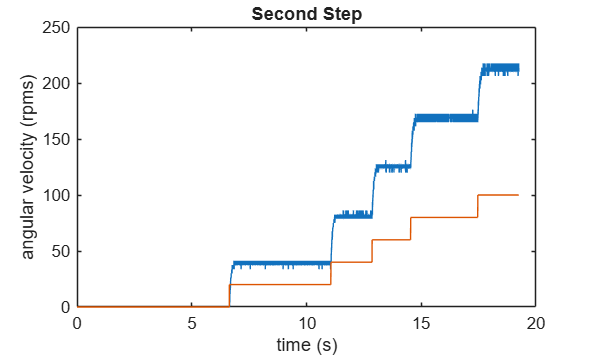


figure; 
plot(t2, y2);
hold on; 
plot(t2, u2);
title('Second Step')
xlabel("time (s)")
ylabel("angular velocity (rpms)")

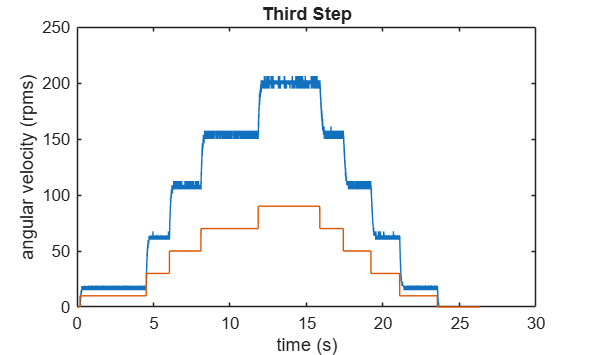


figure; 
plot(t3, y3);
hold on; 
plot(t3, u3);
title('Third Step')
xlabel("time (s)")
ylabel("angular velocity (rpms)")

Splitting the data into 3 steps

% Applying the cleaning function to start all steps from t=0
[u1, y1, t1, t_step_1] = ajustarEscalon(u1, y1, t1, fromy=30, toy=50);

Escalón 30 -> 50 ajustado: 433 puntos | t = 0.00 s a 2.16 s (t_abs_inicio = 7.00 s)


[u2, y2, t2, t_step_2] = ajustarEscalon(u2, y2, t2, fromy=40, toy=60);

Escalón 40 -> 60 ajustado: 337 puntos | t = 0.00 s a 1.68 s (t_abs_inicio = 12.86 s)


[u3, y3, t3, t_step_3] = ajustarEscalon(u3, y3, t3, fromy=30, toy=50);

Escalón 30 -> 50 ajustado: 413 puntos | t = 0.00 s a 2.06 s (t_abs_inicio = 6.04 s)


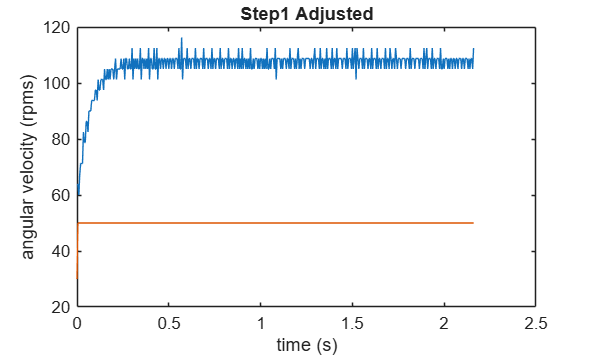


% Unificar las 3 estructuras independientes en una sola variable 'datos'
datos.step1.u = u1; 
datos.step1.y = y1; 
datos.step1.t = t1; 

datos.step2.u = u2; 
datos.step2.y = y2; 
datos.step2.t = t2; 

datos.step3.u = u3; 
datos.step3.y = y3; 
datos.step3.t = t3; 

%graficar
figure;
plot(datos.step1.t, datos.step1.y)
hold on; 
plot(datos.step1.t, datos.step1.u)
title('Step1 Adjusted')
xlabel("time (s)")
ylabel("angular velocity (rpms)")

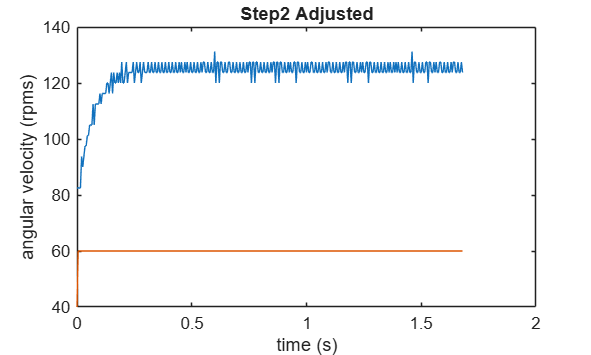


figure;
plot(datos.step2.t, datos.step2.y)
hold on; 
plot(datos.step2.t, datos.step2.u)
title('Step2 Adjusted')
xlabel("time (s)")
ylabel("angular velocity (rpms)")

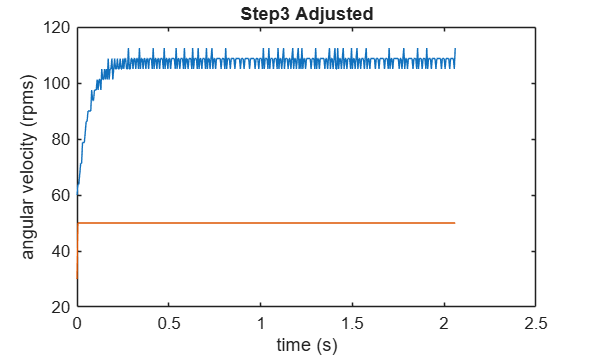


figure;
plot(datos.step3.t, datos.step3.y)
hold on; 
plot(datos.step3.t, datos.step3.u)
title('Step3 Adjusted')
xlabel("time (s)")
ylabel("angular velocity (rpms)")

Identification as FOPDT


=== Ajuste FOPDT Sincronizado ===
Ganancia (K):            2.1946
Constante de tiempo (t): 0.0568 s
Tiempo muerto (theta):   0.0092 s
MSE del ajuste:          6.610619
NRMSE:                   0.0457 (4.57% del rango)
Fit Percentage:          62.10%

G_fopdt =
 
                        2.195
  exp(-0.00921*s) * -------------
                    0.05675 s + 1
 
Continuous-time transfer function.


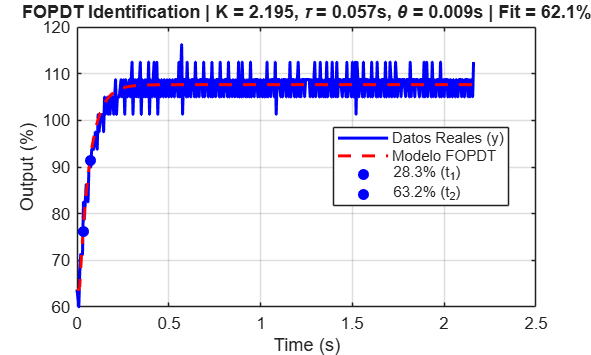

G1 = []; G2 = [];  G3 = []; 

% Identificar los parámetros para el step 1
[K1, tau1, theta1, G1, mse1] = identificarFOPDT(datos.step1.u, datos.step1.y, datos.step1.t);


=== Ajuste FOPDT Sincronizado ===
Ganancia (K):            2.1375
Constante de tiempo (t): 0.0610 s
Tiempo muerto (theta):   0.0000 s
MSE del ajuste:          5.368805
NRMSE:                   0.0475 (4.75% del rango)
Fit Percentage:          67.14%

G_fopdt =
 
      2.138
  -------------
  0.06096 s + 1
 
Continuous-time transfer function.


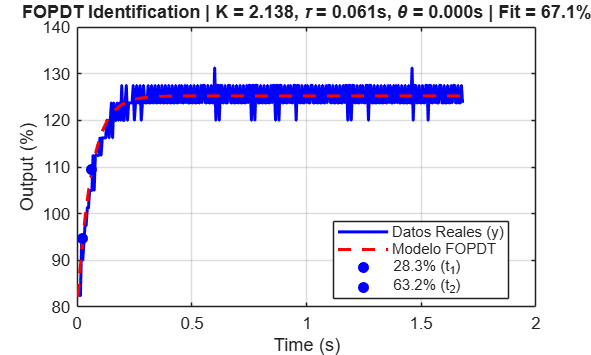


% Identificar para el step 2 (si existe)
if isfield(datos, 'step2')
    [K2, tau2, theta2, G2, mse2] = identificarFOPDT(datos.step2.u, datos.step2.y, datos.step2.t);
end


=== Ajuste FOPDT Sincronizado ===
Ganancia (K):            2.4062
Constante de tiempo (t): 0.0594 s
Tiempo muerto (theta):   0.0000 s
MSE del ajuste:          4.757470
NRMSE:                   0.0415 (4.15% del rango)
Fit Percentage:          67.16%

G_fopdt =
 
      2.406
  -------------
  0.05941 s + 1
 
Continuous-time transfer function.


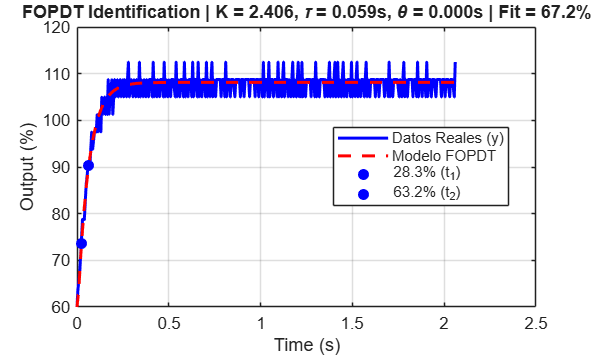


% Identificar para el step 3 (si existe)
if isfield(datos, 'step3')
    [K3, tau3, theta3, G3, mse3] = identificarFOPDT(datos.step3.u, datos.step3.y, datos.step3.t);
end


display("=== Funciones de Transferencia ===")

    "=== Funciones de Transferencia ==="



G1.OutputDelay = 0


G1 =
 
      2.195
  -------------
  0.05675 s + 1
 
Continuous-time transfer function.


G2


G2 =
 
      2.138
  -------------
  0.06096 s + 1
 
Continuous-time transfer function.


G3


G3 =
 
      2.406
  -------------
  0.05941 s + 1
 
Continuous-time transfer function.


## Model Adjustment

Adjusting parameters to match the Non-Parametric TF for each motor


=== PARAMETRIC FIT: G1 ===
Param       Initial       Fitted     Change
beta     1.6583e-06   1.7631e-06      +6.3%
J        8.2636e-07   3.1510e-06    +281.3%
Kv       8.8479e-03   1.0121e-02     +14.4%
Fit Percentage: 99.33%

=== FITTED TF: G1 [rad/s / V] ===

G_fit =
 
         3.675e06
  -----------------------
  s^2 + 2175 s + 3.841e04
 
Continuous-time transfer function.


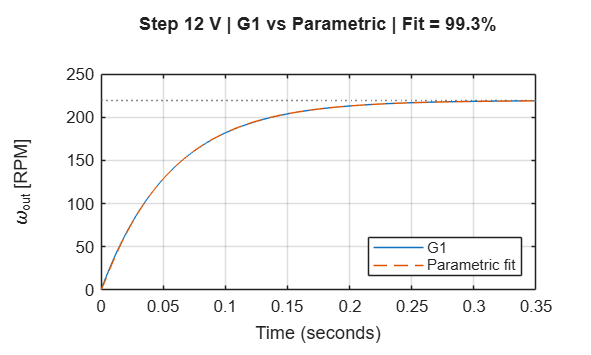

k_si = (100/12) * (2*pi*N/60);   % RPM(out)/% PWM -> rad/s(motor)/V

% Converting to SI units
G1_si = G1 * k_si;
G2_si = G2 * k_si;
G3_si = G3 * k_si;

% Model Adjustment
p0 = [beta, J, Kv];

[par1, Gp1, fit1] = ajustarParametrico(G1_si, Ra, La, p0, Name="G1");


=== PARAMETRIC FIT: G2 ===
Param       Initial       Fitted     Change
beta     1.6583e-06   1.8584e-06     +12.1%
J        8.2636e-07   3.5684e-06    +331.8%
Kv       8.8479e-03   1.0391e-02     +17.4%
Fit Percentage: 99.38%

=== FITTED TF: G2 [rad/s / V] ===

G_fit =
 
         3.332e06
  -----------------------
  s^2 + 2174 s + 3.575e04
 
Continuous-time transfer function.


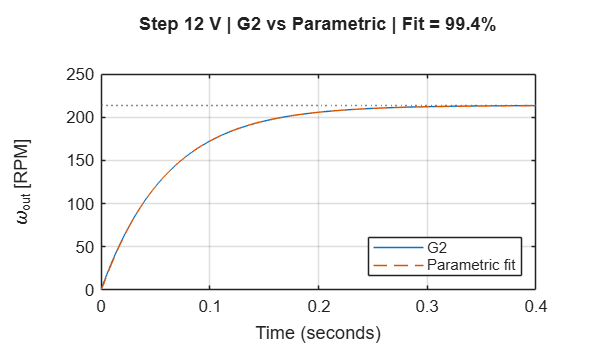

[par2, Gp2, fit2] = ajustarParametrico(G2_si, Ra, La, p0, Name="G2");


=== PARAMETRIC FIT: G3 ===
Param       Initial       Fitted     Change
beta     1.6583e-06   1.4665e-06     -11.6%
J        8.2636e-07   2.7440e-06    +232.1%
Kv       8.8479e-03   9.2306e-03      +4.3%
Fit Percentage: 99.36%

=== FITTED TF: G3 [rad/s / V] ===

G_fit =
 
         3.849e06
  -----------------------
  s^2 + 2174 s + 3.669e04
 
Continuous-time transfer function.


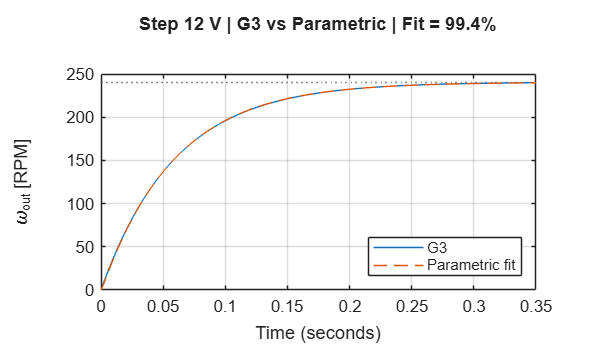

[par3, Gp3, fit3] = ajustarParametrico(G3_si, Ra, La, p0, Name="G3");

## Model Graphs

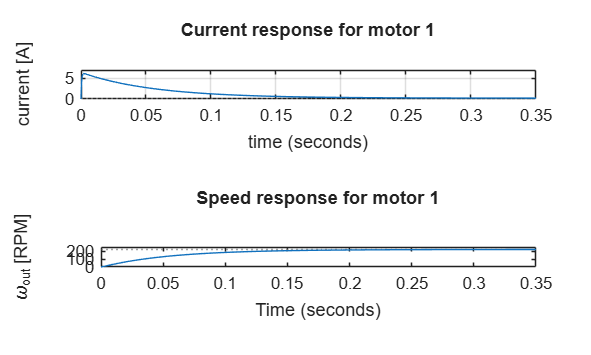

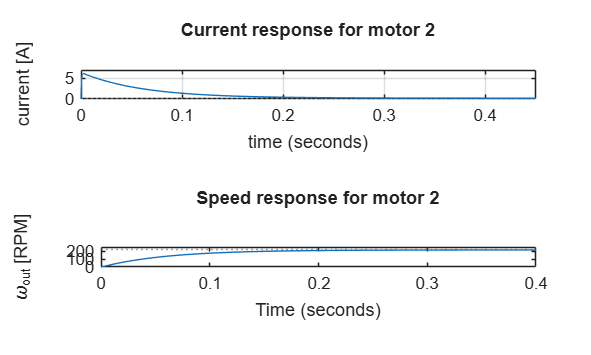

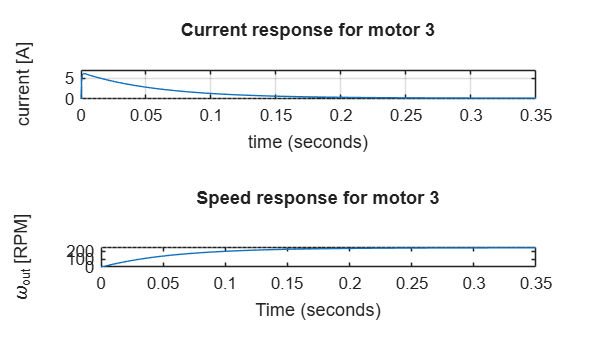

pars = {par1, par2, par3};

for k = 1:3
    p = pars{k};
    
    A_ss = [-Ra/La, -p.Kv/La; p.Kv/p.J, -p.beta/p.J];
    B_ss = [1/La; 0];
    C_ss = [0 1]; 
    D_ss = 0;
    
    sys_omega   = ss(A_ss, B_ss, C_ss, D_ss);
    sys_current = ss(A_ss, B_ss, [1 0], D_ss);
    
    figure('Name', sprintf('Sistema k = %d', k), 'NumberTitle', 'off');
    
    % Current Graph
    subplot(2, 1, 1);
    step(sys_current * 12);
    title(sprintf('Current response for motor %d', k));
    xlabel('time');
    ylabel('current [A]');
    grid on;
    
    % Speed Graph (gearbox output)
    subplot(2, 1, 2);
    step(sys_omega * 12 * 60/(2*pi*N));      % RPM at output shaft
    title(sprintf('Speed response for motor %d', k));
    ylabel('\omega_{out} [RPM]');
end

## Discretization

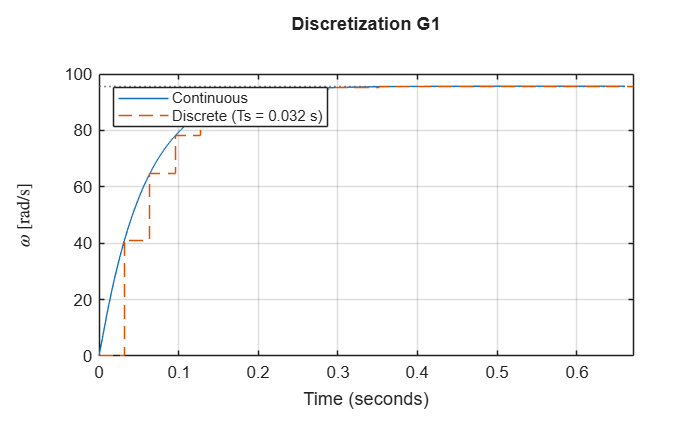


=== DISCRETIZATION ANALYSIS: G1 ===
Ts range (A) plant = 0.02947 - 0.03369 s
Ts used            = 0.032 s  [user-defined]
Routh : -0.0105 < K < 0.0385
Jury  : -0.0105 < K < 0.0385


Ts = 0.032;   
[Gd1, KR1, KJ1] = discretizationAnalysis(Gp1, Ts=Ts, Name="G1");

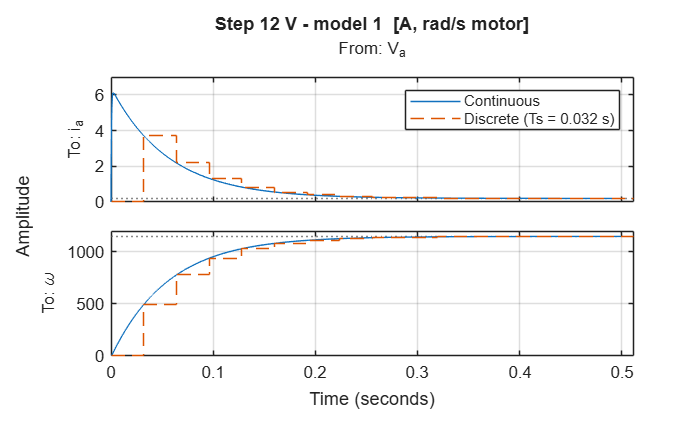

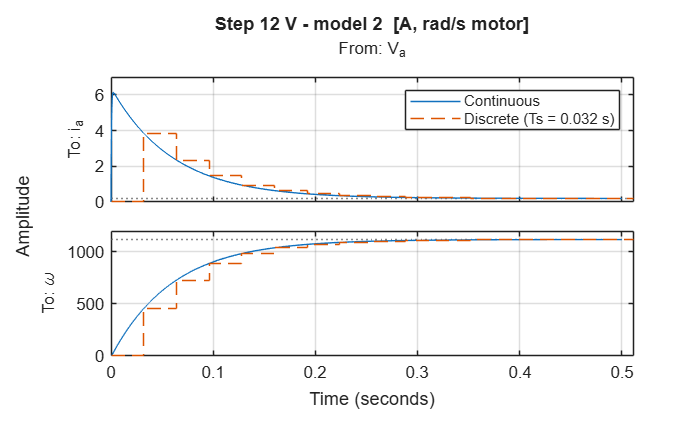

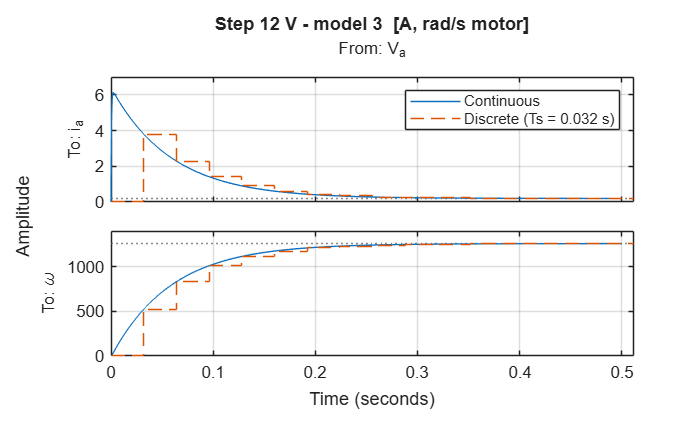


pars = {par1, par2, par3};
sysc = cell(1,3);  sysd = cell(1,3);

for k = 1:3
    p  = pars{k};
    A2 = [-Ra/La,     -p.Kv/La;
        p.Kv/p.J,  -p.beta/p.J];
    B2 = [1/La; 0];
    C2 = eye(2);                 % ambas salidas, para graficar
    D2 = zeros(2,1);

    sysc{k} = ss(A2, B2, C2, D2, 'StateName', {'i_a','\omega'}, ...
        'InputName', 'V_a', 'OutputName', {'i_a','\omega'});
    sysd{k} = c2d(sysc{k}, Ts, 'zoh');

    figure('Name', sprintf('Model %d: continuous vs discrete', k), 'NumberTitle', 'off');
    step(12*sysc{k}, 12*sysd{k}, '--', 0.5); grid on;
    legend('Continuous', sprintf('Discrete (Ts = %g s)', Ts));
    title(sprintf('Step 12 V - model %d  [A, rad/s motor]', k));
end


Ad = sysd{k}.A;   Bd = sysd{k}.B;   Cd = [0 1];